clc;
clear;
format shortE;

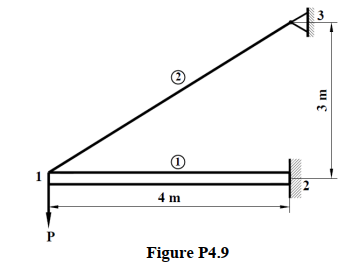

Taking inputs about elements

nel=1%input("Enter the number of beam elements: ");

nel =      1


nt=1%input("Enter the number of truss elements: ");

nt =      1


nnd= nel+nt+1; %Number of nodes
dof=3*nnd-1; % Degree of freedom for a planar beam and a truss
E=200e9;
I=0.8e-4;
A=10e-4; %Area of the beam
At=5e-4; %Area of the truss element
L=4;
Lt=5;
s=[0]; %angle of beam
thetat=[atand(3/4)] %angle of truss

thetat =    3.6870e+01


P=10e3;
conn=[1 2];%connectivity matrix for beam

Creating empty global stiffness matrix, force and displacement vector

gstiff=zeros(dof,dof);
gforce=zeros(dof,1);
gdisp=zeros(dof,1);
kel=cell(nel,1);

Calculating global stiffness matrix

for n=1:nel
    i=conn(n,1);
    j=conn(n,2);
    ix= 3*i-2;
    iy= 3*i-1;
    iz= 3*i;
    jx=3*j-2;
    jy=3*j-1;
    jz= 3*j;
    trig=[cosd(s(n)) sind(s(n)) 0
        -sind(s(n)) cosd(s(n)) 0
        0 0 1];
    c=zeros(3,3);
    lambda=[trig c;c trig];
    local_stiff=[A*E/L 0 0 -A*E/L 0 0
    0 12*E*I/L^3 6*E*I/L^2 0 -12*E*I/L^3 6*E*I/L^2
    0 6*E*I/L^2 4*E*I/L 0 -6*E*I/L^2 2*E*I/L
    -A*E/L 0 0 A*E/L 0 0
    0 -12*E*I/L^3 -6*E*I/L^2 0 12*E*I/L^3 -6*E*I/L^2
    0 6*E*I/L^2 2*E*I/L 0 -6*E*I/L^2 4*E*I/L
    ]

    global_ele_stiff= lambda' * local_stiff * lambda;
    gstiff([ix,iy,iz,jx,jy,jz],[ix,iy,iz,jx,jy,jz])= gstiff([ix,iy,iz,jx,jy,jz],[ix,iy,iz,jx,jy,jz])+global_ele_stiff;
end

local_stiff =    5.0000e+07            0            0  -5.0000e+07            0            0
            0   3.0000e+06   6.0000e+06            0  -3.0000e+06   6.0000e+06
            0   6.0000e+06   1.6000e+07            0  -6.0000e+06   8.0000e+06
  -5.0000e+07            0            0   5.0000e+07            0            0
            0  -3.0000e+06  -6.0000e+06            0   3.0000e+06  -6.0000e+06
            0   6.0000e+06   8.0000e+06            0  -6.0000e+06   1.6000e+07


Including truss in global stiffness

for q=1:nt
    k=At*E/Lt;
    Ke_local=[k -k; -k k]
    lambdat=[cosd(thetat) sind(thetat) 0 0; 0 0 cosd(thetat) sind(thetat)];
    Ke_global=lambdat'*Ke_local*lambdat
    disp("Consider the orientation of spring in finding common node and displacement to beam. ");
    h=[1 2 7 8]%input("Enter the displacements affected by the spring as per position in global stiffness matrix: ");
    gstiff(h,h)=gstiff(h,h)+ Ke_global
end

Ke_local =     20000000   -20000000
   -20000000    20000000


Ke_global =     12800000     9600000   -12800000    -9600000
     9600000     7200000    -9600000    -7200000
   -12800000    -9600000    12800000     9600000
    -9600000    -7200000     9600000     7200000


Consider the orientation of spring in finding common node and displacement to beam. 


h =      1     2     7     8


gstiff =    6.2800e+07   9.6000e+06            0  -5.0000e+07            0            0  -1.2800e+07  -9.6000e+06
   9.6000e+06   1.0200e+07   6.0000e+06            0  -3.0000e+06   6.0000e+06  -9.6000e+06  -7.2000e+06
            0   6.0000e+06   1.6000e+07            0  -6.0000e+06   8.0000e+06            0            0
  -5.0000e+07            0            0   5.0000e+07            0            0            0            0
            0  -3.0000e+06  -6.0000e+06            0   3.0000e+06  -6.0000e+06            0            0
            0   6.0000e+06   8.0000e+06            0  -6.0000e+06   1.6000e+07            0            0
  -1.2800e+07  -9.6000e+06            0            0            0            0   1.2800e+07   9.6000e+06
  -9.6000e+06  -7.2000e+06            0            0            0            0   9.6000e+06   7.2000e+06


gstiff

gstiff =    6.2800e+07   9.6000e+06            0  -5.0000e+07            0            0  -1.2800e+07  -9.6000e+06
   9.6000e+06   1.0200e+07   6.0000e+06            0  -3.0000e+06   6.0000e+06  -9.6000e+06  -7.2000e+06
            0   6.0000e+06   1.6000e+07            0  -6.0000e+06   8.0000e+06            0            0
  -5.0000e+07            0            0   5.0000e+07            0            0            0            0
            0  -3.0000e+06  -6.0000e+06            0   3.0000e+06  -6.0000e+06            0            0
            0   6.0000e+06   8.0000e+06            0  -6.0000e+06   1.6000e+07            0            0
  -1.2800e+07  -9.6000e+06            0            0            0            0   1.2800e+07   9.6000e+06
  -9.6000e+06  -7.2000e+06            0            0            0            0   9.6000e+06   7.2000e+06


Applying boundary conditions of externally applied loads

load_vector=2%input("Enter the position of external loads applied as they would be positioned in global force vector: ");

load_vector =      2


extloads=-P%input("Enter the external loads applied :");

extloads =       -10000


gforce(load_vector)=extloads

gforce =            0
      -10000
           0
           0
           0
           0
           0
           0


gforce

gforce =            0
      -10000
           0
           0
           0
           0
           0
           0


Calculation of required displacements

g=[1 2 3]%input("Enter the displacements to be found according to their position in the stiffness matrix:");

g =      1     2     3


Extracting the required stiffness matrix

gstiff1=gstiff(g,g)

gstiff1 =    6.2800e+07   9.6000e+06            0
   9.6000e+06   1.0200e+07   6.0000e+06
            0   6.0000e+06   1.6000e+07


gforce1=gforce(g)

gforce1 =            0
      -10000
           0


disp1=gstiff1\gforce1

disp1 =    2.3581e-04
  -1.5426e-03
   5.7848e-04


gdisp(g)=disp1;

The required nodal displacements and support reactions are:-

gdisp

gdisp =    2.3581e-04
  -1.5426e-03
   5.7848e-04
            0
            0
            0
            0
            0


force=gstiff*gdisp

force =             0
  -1.0000e+04
            0
  -1.1791e+04
   1.1570e+03
  -4.6279e+03
   1.1791e+04
   8.8430e+03
